# GEOAISWEB v. 1.4.1

Trata-se de portal acessível no *link* [https://geoaisweb.decea.mil.br/](https://geoaisweb.decea.mil.br/)  que tem como responsável o DECEA, contendo registros dos sistemas de radionavegação aeronáutica NDB, VOR e DME.

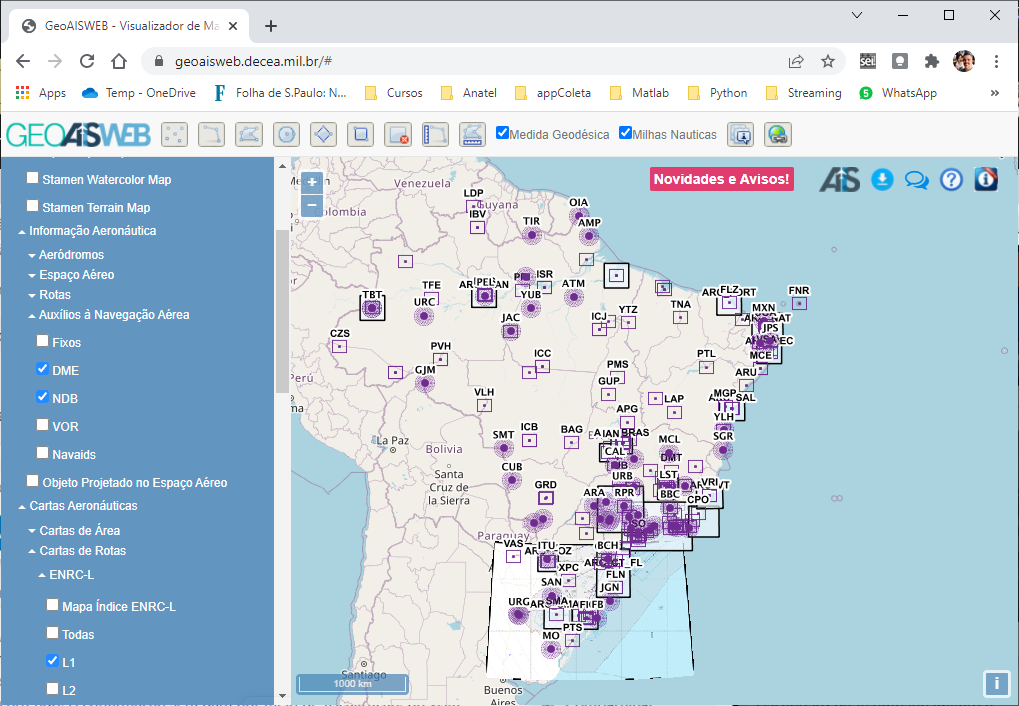

Sintaxe:

Versão: **08/03/2022**

function [GeoAiswebDB, GeoAiswebDB_ExtractDate] = Fcn_GeoAiswebDB

    proj = matlab.project.rootProject;
    if isempty(proj)
        error('O projeto "PmecDB" deve ser aberto antes de executada uma das suas funções.')
    end

    GeoAiswebDB = table('Size', [0, 6],                                                            ...
                        'VariableTypes', {'single', 'single', 'single', 'cell', 'int16', 'int32'}, ...
                        'VariableNames', {'Frequency', 'Latitude', 'Longitude', 'Description', 'Service', 'Station'});

    VOR = webread("https://geoaisweb.decea.mil.br/geoserver/ICA/ows?service=WFS&version=1.0.0&request=GetFeature&typeName=ICA:vor&outputFormat=application%2Fjson");
    DME = webread("https://geoaisweb.decea.mil.br/geoserver/ICA/ows?service=WFS&version=1.0.0&request=GetFeature&typeName=ICA:dme&outputFormat=application%2Fjson");
    NDB = webread("https://geoaisweb.decea.mil.br/geoserver/ICA/ows?service=WFS&version=1.0.0&request=GetFeature&typeName=ICA:ndb&outputFormat=application%2Fjson");

    % VOR
    VOR = VOR.features;
    for ii = 1:height(VOR)
        Frequency   = Fcn_FrequencyUnit(VOR(ii).properties.frequency, ...
                                        VOR(ii).properties.frequnits);

        Description = sprintf('[GEOAISWEB] %s - %s %s', VOR(ii).properties.tipo,    ...
                                                        VOR(ii).properties.txtname, ...
                                                        VOR(ii).properties.txtrmk);
        Description = deblank(erase(Description, newline));

        GeoAiswebDB(end+1,:) = {Frequency,                    ...
                                VOR(ii).properties.latitude,  ...
                                VOR(ii).properties.longitude, ...
                                Description, -1, -1};
    end

    % DME
    channelTab = readtable('20210331 - VOR_ILS_DME Channel.xlsx');

    DME = DME.features;
    for ii = 1:height(DME)
        Channel = sprintf('%d%s', DME(ii).properties.valchannel, ...
                                  DME(ii).properties.codechanne);

        idx     = find(strcmpi(channelTab.Channel, Channel), 1);
        if ~isempty(idx)
            Frequency   = channelTab.DMEground(idx);
            Description = sprintf('[GEOAISWEB] %s - %s %s', DME(ii).properties.tipo,    ...
                                                            DME(ii).properties.txtname, ...
                                                            Channel);
            Description = deblank(erase(Description, newline));
    
            GeoAiswebDB(end+1,:) = {Frequency,                  ...
                                    DME(ii).properties.geolat,  ...
                                    DME(ii).properties.geolong, ...
                                    Description, -1, -1};
        end
    end

    % NDB
    NDB = NDB.features;
    for ii = 1:height(NDB)
        Frequency   = Fcn_FrequencyUnit(NDB(ii).properties.valfreq, ...
                                        NDB(ii).properties.uomfreq);

        Description = sprintf('[GEOAISWEB] %s - %s %s', NDB(ii).properties.tipo,    ...
                                                        NDB(ii).properties.txtname, ...
                                                        NDB(ii).properties.txtrmk);
        Description = deblank(erase(Description, newline));

        GeoAiswebDB(end+1,:) = {Frequency,                  ...
                                NDB(ii).properties.geolat,  ...
                                NDB(ii).properties.geolong, ...
                                Description, -1, -1};
    end
    GeoAiswebDB = Misc_AnatelDBQuery(GeoAiswebDB);

    GeoAiswebDB = sortrows(GeoAiswebDB, 'Frequency');
    GeoAiswebDB_ExtractDate = datestr(now, 'dd/mm/yyyy HH:MM:SS');


    % MAT and XLSX files
    fileMAT = fullfile(proj.RootFolder, 'Temp', 'GeoAiswebDB.mat');
    save(fileMAT, 'GeoAiswebDB', 'GeoAiswebDB_ExtractDate', '-v7.3')
    
    GeoAiswebXLS = GeoAiswebDB;
    GeoAiswebXLS.Frequency = round(double(GeoAiswebXLS.Frequency), 3);

    fileXLS = replace(fileMAT, '.mat', '.xlsx');
    writematrix(GeoAiswebDB_ExtractDate, fileXLS, 'Sheet', 'ExtractDate')
    writetable(GeoAiswebXLS,             fileXLS, 'Sheet', 'DataBase', 'WriteMode', 'overwritesheet')

end



function Frequency = Fcn_FrequencyUnit(freq, unit)

    if     strcmpi(unit, 'Hz');  Frequency = freq/1e+6;
    elseif strcmpi(unit, 'kHz'); Frequency = freq/1000;
    elseif strcmpi(unit, 'MHz'); Frequency = freq;
    elseif strcmpi(unit, 'GHz'); Frequency = freq*1000;
    end

end